# Labolatorium 4

# Modulacja częstotliwości

### Opis Problemu:

Ćwiczenie polegało na:

1. Modulacja FM. Dobrać parametry fc, fs, Ac. Rozważamy dwa różne sygnały modulowane:

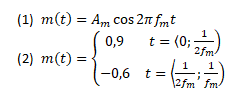

· Sprawdzić wpływ parametrów kf (czułość modulatora) oraz β (wskaźnik modulacji).

· Wykreśl widma sygnałów. Przeanalizuj wpływ parametrów.

· W każdym z przypadków wyznacz moc sygnałów modulujących, nośnych i zmodulowanego (sprawność).

· Wykonaj demodulację sygnału poprzez wyznaczenie obwiedni zespolonej (*), a następnie zróżniczkowanie widma fazowego otrzymanego sygnału.

 gdzie 𝑠̂(𝑡) to transformata Hilberta sygnału s(t) (*) Wyniki porównaj z wbudowanymi funkcjami Matlaba fmmod i fmdemod.

### Podstawy matematyczne:

#### Sygnał:

clc; clear; close all;

fs = 100000; %częstotliwość próbkowania
t = 0:1/fs:1-(1/fs);
th =  0:1/fs:1 - 2 * (1/fs);

%parametry nośnej
Ac = 1;
fc =8000;

%parametry sygnału modulującego
Am = 1;
fm = 10;

delta_f = fc - fm;
kf = delta_f / Am  %czułość modulatora

kf = 7990

B = (kf * Am) / fm  %wskaźnik modulacji

B = 799

%sygnał modulujący
signal = Am*cos(2*pi*fm*t);

%sygnał zmodulowany
Sfm = Ac*cos(2*pi*fc*t + B*sin(2*pi*fm*t));

%dft
dft_signal = fft(signal);
dft_Sfm = fft(Sfm);

freq=(-length(t)/2:(length(t)/2 - 1));

%moc c_rms = rms(c)^2;
moc_sygnalu_modulujacego = rms(signal)^2

moc_sygnalu_modulujacego = 0.5000

moc_sygnalu_zmodulowanego = rms(Sfm)^2

moc_sygnalu_zmodulowanego = 0.5162

sprawnosc = (moc_sygnalu_modulujacego / moc_sygnalu_zmodulowanego) * 100

sprawnosc = 96.8709

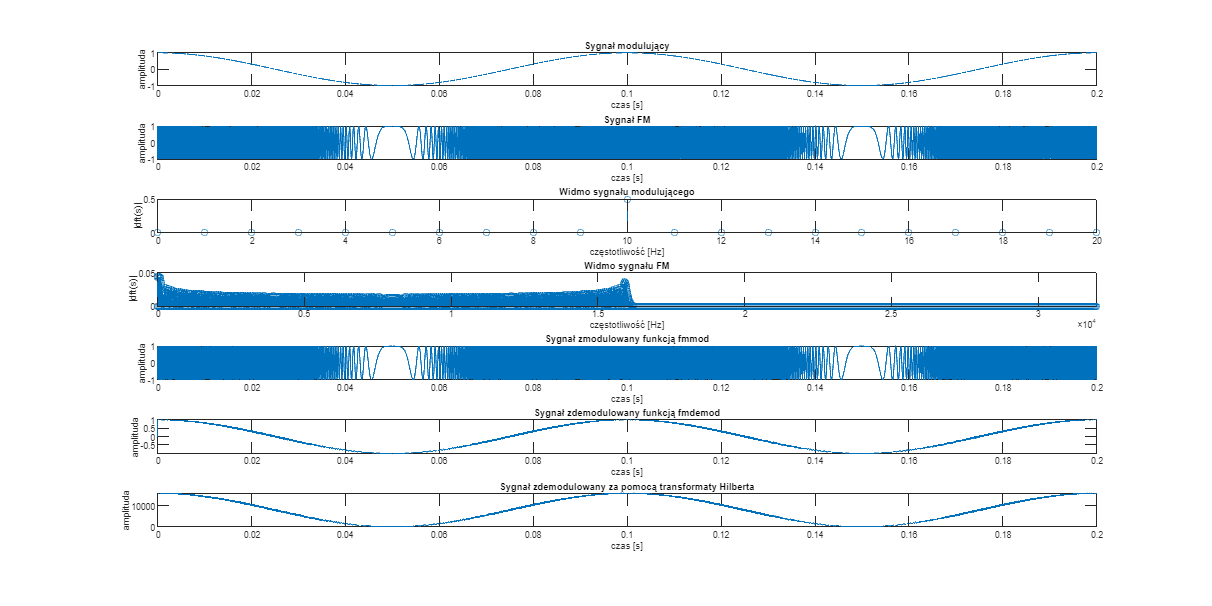

%modulacje demodulacje
modulated_signal = fmmod(signal, fc, fs, delta_f);

demodulated_signal = fmdemod(modulated_signal, fc, fs, delta_f);
w = unwrap(angle(hilbert(Sfm)));
hilbert_demodulated_signal = ((diff(w)/(2*pi*1/fs)));

fig = figure;
fig.Position = [0, 0, 2000, 1000];

subplot(7,1,1)
plot(t, signal)
xlim([0, 2/fm])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał modulujący')

subplot(7,1,2)
plot(t, Sfm)
xlim([0, 2/fm])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał FM')

subplot(7,1,3)
stem(freq, abs(fftshift(dft_signal))/length(t))
xlim([0, fm * 2])
xlabel('częstotliwość [Hz]')
ylabel('|dft(s)|')
title('Widmo sygnału modulującego')

subplot(7,1,4)
stem(freq, abs(fftshift(dft_Sfm))/length(t))
xlim([0, fc * 4])
xlabel('częstotliwość [Hz]')
ylabel('|dft(s)|')
title('Widmo sygnału FM')

subplot(7,1,5)
plot(t, modulated_signal)
xlim([0, 2/fm])
xlabel('czas [s]')
ylabel('amplituda')
title('Sygnał zmodulowany funkcją fmmod')

subplot(7,1,6)
plot(t, demodulated_signal)
xlim([0, 2/fm])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał zdemodulowany funkcją fmdemod')

subplot(7,1,7)
plot(th, hilbert_demodulated_signal)
xlim([0, 2/fm])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał zdemodulowany za pomocą transformaty Hilberta')

#### Sygnał:

clc; clear; close all;

fs = 100000; %częstotliwość próbkowania
t = 0:1/fs:1-(1/fs);
th =  0:1/fs:1 - 2 * (1/fs);

%parametry nośnej
Ac = 1;
fc =1000;

%parametry sygnału modulującego
Am = 1;
fm = 10;

delta_f = fc - fm;
kf = delta_f / Am  %czułość modulatora

kf = 990

B = (kf * Am) / fm  %wskaźnik modulacji

B = 99

%sygnał modulujący
signal = Am * square(2*pi*fm*t) * 0.75 + 0.15;

%sygnał zmodulowany
Sfm = fmmod(signal, fc, fs, delta_f);

%dft
dft_signal = fft(signal);
dft_Sfm = fft(Sfm);

freq=(-length(t)/2:(length(t)/2 - 1));

%moc c_rms = rms(c)^2;
moc_sygnalu_modulujacego = rms(signal)^2

moc_sygnalu_modulujacego = 0.5850

moc_sygnalu_zmodulowanego = rms(Sfm)^2

moc_sygnalu_zmodulowanego = 0.5000

sprawnosc = (moc_sygnalu_modulujacego / moc_sygnalu_zmodulowanego) * 100

sprawnosc = 117.0008

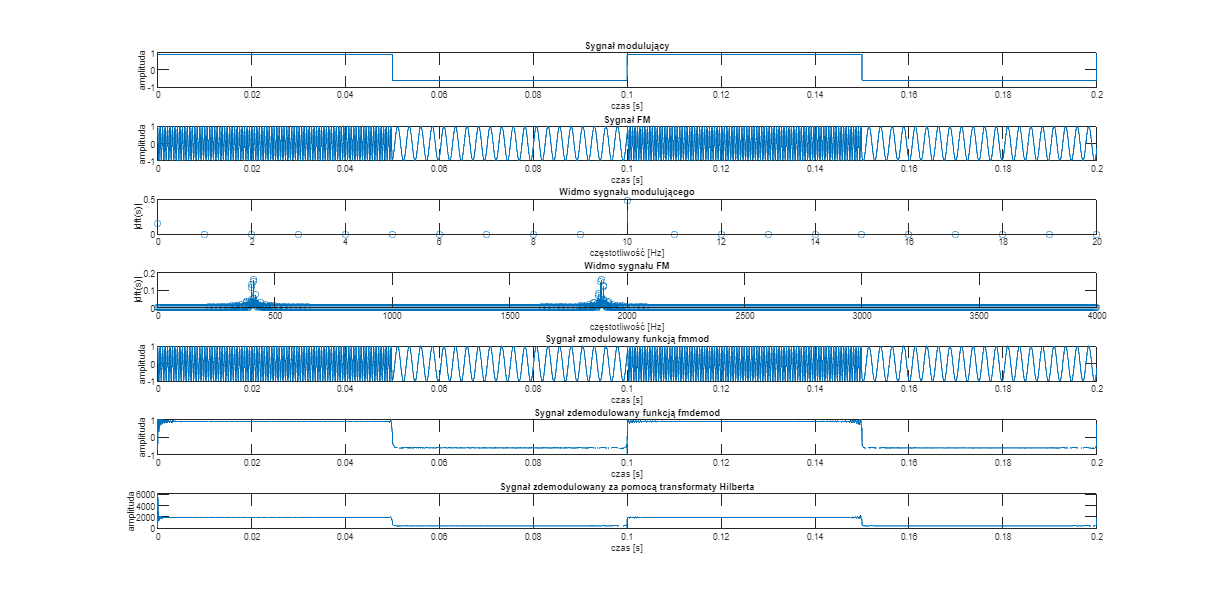

%modulacje demodulacje
modulated_signal = fmmod(signal, fc, fs, delta_f);

demodulated_signal = fmdemod(modulated_signal, fc, fs, delta_f);
w = unwrap(angle(hilbert(Sfm)));
hilbert_demodulated_signal = ((diff(w)/(2*pi*1/fs)));

fig = figure;
fig.Position = [0, 0, 2000, 1000];

subplot(7,1,1)
plot(t, signal)
xlim([0, 2/fm])
ylim([-Am, Am])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał modulujący')

subplot(7,1,2)
plot(t, Sfm)
xlim([0, 2/fm])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał FM')

subplot(7,1,3)
stem(freq, abs(fftshift(dft_signal))/length(t))
xlim([0, fm * 2])
xlabel('częstotliwość [Hz]')
ylabel('|dft(s)|')
title('Widmo sygnału modulującego')

subplot(7,1,4)
stem(freq, abs(fftshift(dft_Sfm))/length(t))
xlim([0, fc * 4])
xlabel('częstotliwość [Hz]')
ylabel('|dft(s)|')
title('Widmo sygnału FM')

subplot(7,1,5)
plot(t, modulated_signal)
xlim([0, 2/fm])
xlabel('czas [s]')
ylabel('amplituda')
title('Sygnał zmodulowany funkcją fmmod')

subplot(7,1,6)
plot(t, demodulated_signal)
xlim([0, 2/fm])
ylim([-Am, Am])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał zdemodulowany funkcją fmdemod')

subplot(7,1,7)
plot(th, hilbert_demodulated_signal)
xlim([0, 2/fm])
xlabel("czas [s]")
ylabel("amplituda")
title('Sygnał zdemodulowany za pomocą transformaty Hilberta')

2. Wąskopasmowa modulacja FM. Dobrać parametry fc, fs, Ac.

· Sprawdzić wpływ parametrów kf (czułość modulatora), β wskaźnik modulacji oraz relacje Am/ /Ac

· Wykreśl sygnały i ich widma. Przeanalizuj wpływ parametrów.

· Wykonaj demodulację sygnału.

3. Szerokopasmowa modulacja FM. Wykonaj modulację jednotonową w oparciu o funkcje Bessela pierwszego rodzaju. Porównaj kryterium jednoprocentowe (amplituda składowych przekracza 1% amplitudy sygnału niezmodulowanego) i regułę Carsona w zależności od parametrów sygnałów składowych, czułości modulacji, β (wskaźnik modulacji) pod względem wpływu na pasmo sygnału FM.